# cwEDMR on Pin SC using Elexsys

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% File and Run options
Opt.LFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\20210617';
Opt.Ldir0 = dir([Opt.LFolder, '\*_0Deg.DTA']);
Opt.LPaths = [Opt.LFolder, '\', Opt.Ldir0.name];
Opt.Ldir90 = dir([Opt.LFolder, '\*_90Deg.DTA']);

Opt.SFolder = 'D:\Profile\qse\Files\_EDMRoC pinSC\Images';

% Field offset (obtained from field_calibration_2021_06_17)
B0Offset = 0.89 - 8.1;
Idc = [3.98 9.45 19.1 34.0 56.3 82.2 112 146 178 216 250 287]; % uA
cw = struct();
idxStart = 5;
ncw = numel(Opt.Ldir0) - idxStart + 1;
for icw = 1:ncw
    iDir = idxStart + icw - 1;
    LPath0_ = [Opt.LFolder, '\', Opt.Ldir0(iDir).name];
    LPath90_ = [Opt.LFolder, '\', Opt.Ldir90(iDir).name];

    [cw(icw).xRaw, cw(icw).yRaw, cw(icw).Params] = ...
        eprloadQuad(LPath0_, LPath90_);
    
    cw(icw).x = (cw(icw).xRaw - B0Offset)/10; % mT
    newStr = strsplit(Opt.Ldir0(iDir).name, '_');
    cw(icw).Title = [strrep(newStr{2}, 'p', '.'), ' ', num2str(Idc(icw)), 'uA'];
end

#### Baseline correction

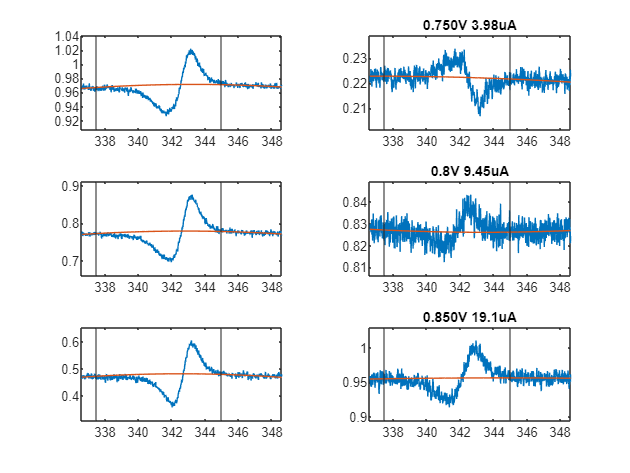

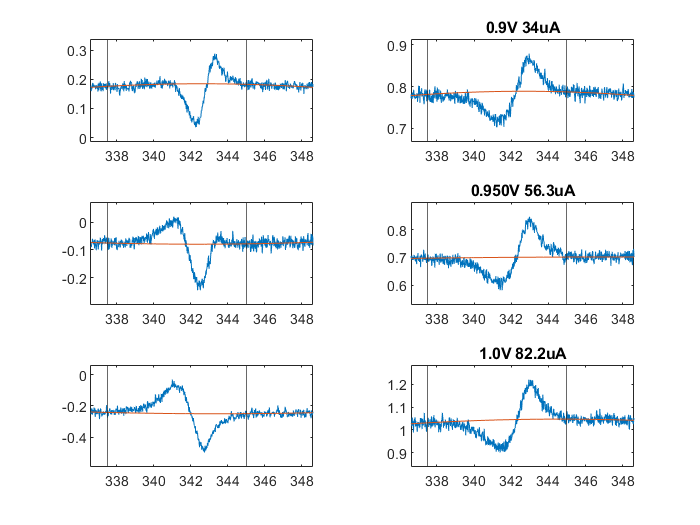

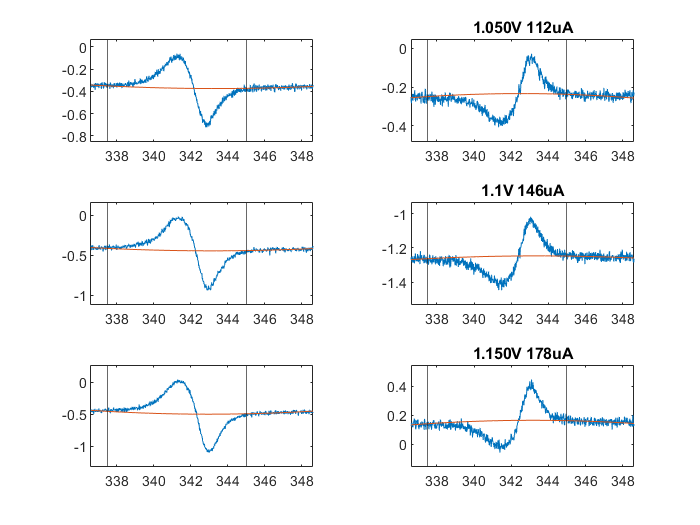

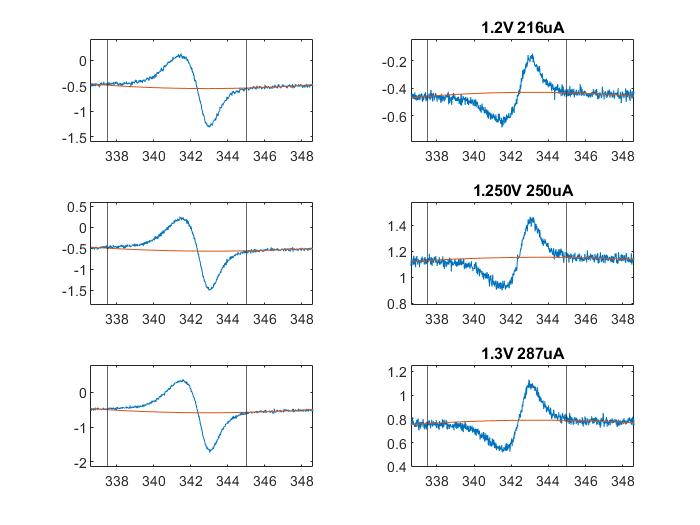

Opt.Bl.Order = 2;
Opt.Bl.Range = [335 337.5; 345 348];

for icw = 1:ncw
    cw(icw).BlOpt = Opt.Bl;
    % y1 is the spectrum baseline corrected but not phase corrected
    [cw(icw).y1, cw(icw).Bl] = ...
        subtractBaseline(cw(icw).x, cw(icw).yRaw, Opt.Bl);
end

nFig = 4;
for iFig = 1:nFig
    figure();
    tiledlayout(ncw/(nFig), 2)
        for icw = (iFig-1)*ncw/nFig + 1:iFig*ncw/nFig; nexttile()
            plot(cw(icw).x, real(cw(icw).yRaw), cw(icw).x, real(cw(icw).Bl));
            xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).yRaw), 0.2));
            xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
            nexttile()
            plot(cw(icw).x, imag(cw(icw).yRaw), cw(icw).x, imag(cw(icw).Bl)); 
            xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(imag(cw(icw).yRaw), 0.2));
            xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
            title(cw(icw).Title)
        end
end

#### Phase correction

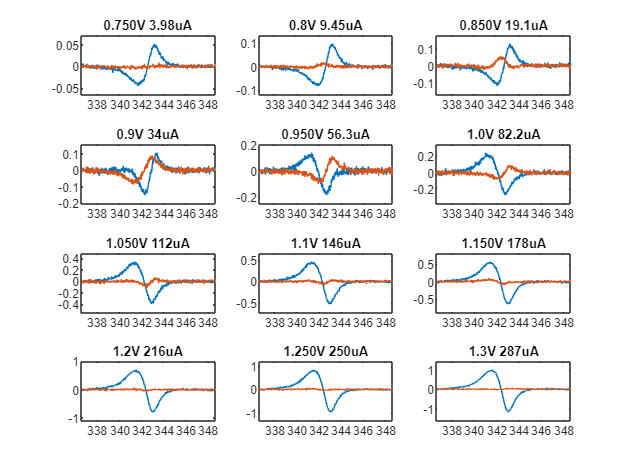

for icw = 1:ncw
    % y2 is the spectrum baseline and phase corrected
    [cw(icw).y2, cw(icw).Phase] = correctPhase(cw(icw).y1, 'Maximum');
    cw(icw).y = real(cw(icw).y2);
end

figure();
tiledlayout('flow');
for icw = 1:ncw;  nexttile; 
    plot(cw(icw).x, real(cw(icw).y2), cw(icw).x, imag(cw(icw).y2));
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).y2), 0.2));
    title(cw(icw).Title)
end

#### Manual

% mpcModel = @(y2, p) y2 * exp(1i*p*pi/180);
% mpcArray = zeros(numel(cw(1).x), 181); % Array of phase corrected data
% mpc = {mpcArray, mpcArray, mpcArray, mpcArray};
% for impc = 1:ncw
%     mpcArray_ = mpcArray;
%     for iP = -90:90
%         mpcArray_(:,90 + iP + 1) = mpcModel(cw(impc).y2, iP*1);
%     end
%     mpc{impc} = mpcArray_;
% 
%     figure()
%     % Phase at which the scrollable starts. Set p0 = 0 if the phase
%     % correction was already done
%     p0 = 0;
%     h1 = ScrollableAxes('Index', 91 + 1 + p0); 
%     plot(h1, cw(impc).x, -90:90, real(mpc{1, impc}));
%     hold on
%     plot(h1, cw(impc).x, -90:90, imag(mpc{1, impc}));
% end

#### Final plot

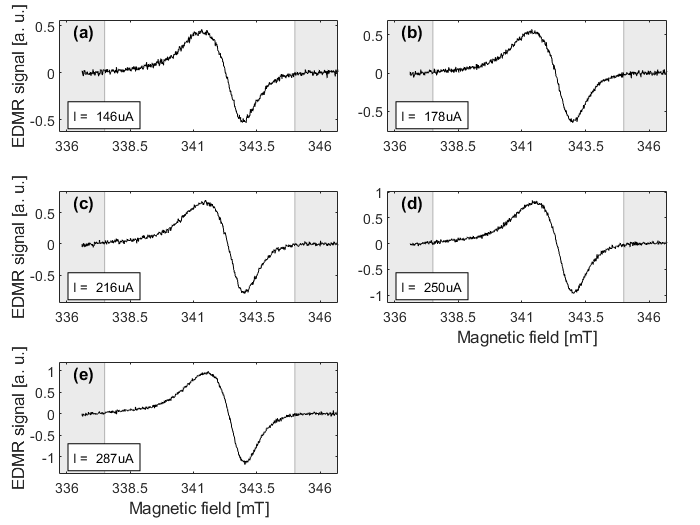

% ID (V and uA): (1.1 146), (1.15 178), (1.2 216), (1.25 250), (1.3 286)
subplotID = ["(a)", "(b)", "(c)", "(d)", "(e)"]; 
figure()
tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
LineW = 0.8;
gC = [0.4660 0.6740 0.1880]; % Green color
pC = [0.4940 0.1840 0.5560]; % Purple color
for icw = ncw - 4:ncw; nexttile
    plot(cw(icw).x, cw(icw).y, 'Color', [0 0 0])
    hold on
    rectangle('Position', [0 -50 Opt.Bl.Range(1, 2) 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    rectangle('Position', [Opt.Bl.Range(2, 1) -50 200 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    
    h = get(gca, 'Children');
    set(gca,'Children',[h(3) h(1) h(2)])
    set(gca, "Layer", "top")
    
    xticks(336:2.5:346); yticks(-1:0.5:1);
    xlim([335.7 346.7]); ylim(setAxLim(cw(icw).y, 0.1));

    if icw == ncw || icw == ncw - 2 || icw == ncw - 4
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > ncw - 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    IDidx = icw - ncw + 5;
    text(0.05, 0.9, subplotID(IDidx), 'Units', 'normalized', ...
        'FontWeight', 'bold', ...
        'FontSize', 10)
    % title(cw(icw).Title)
    annStr = {sprintf('I = %s', cw(icw).Title(end-5:end))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
end

exportStr = input('Export graphics? y/n\n', 's');
if strcmp(exportStr, 'y')
    exportgraphics(gcf, [Opt.SFolder, '/2021-06-17 cwEDMR forward bias.png'])
else
    disp('Graphics not exported')
end

Graphics not exported


#### Save

saveStr = input('Export data to .mat file? y/n\n', 's');
if strcmp(saveStr, 'y')
    cwStruct = cw(8:end);
    nSavecw = numel(cwStruct);
    [x, y] = deal(zeros(numel(cw(1).x), nSavecw));
    for icw = 1:nSavecw
        x(:, icw) = cwStruct(icw).x;
        y(:, icw) = cwStruct(icw).y;
    end
    save([Opt.LFolder, '\cwEDMR_2021_06_17'], 'x', 'y', 'cwStruct');
    % exportgraphics(gcf, [Opt.SFolder, '/2022-06-17 cwEDMR forward bias.png'])
else
    disp('Data not exported')
end